# Model validation, model diagnostics and model selection

Modelling does not end with estimating your model from the data! In this tutorial we will cover important steps in your modelling endeavour:

- *model validation*: ensuring that the model captures the relationship between the regressors and the dependent variable

- *model diagnostics*`: `analyzing how good your model is doing, why it may be failing and how much each regressor contribute to model performance

- *model comparison*: comparing alternative models of your dataset

### Model validation

In model validation, we check whether the empirical relationship between the predictor $\rho(x)$ (i.e. the weighted sum of regressors) and the dependent variable matches the theoretical one. For example, in logistic regression, we expect $p(y) = \sigma(\rho(x))$ where $\sigma$ is the logistic function (a sigmoidal function). We can do this using `plot_data_vs_predictor. `This computed the predictor$\rho(x)$ for every observation, bins these values and compute the average value of the dependent variable in each bin (the black curve). This can be compared to the theoretical one (the blue curve). Here we see a pretty good match (although some small but reliable mismatches appear).

T = load_online_dataset();

loading csv file from url...done


M = gum(T, 'resp ~ Stimulus + lag(response; Lags=1:5)');
M = M.infer();

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29645.683040
Computing posterior covariance...done


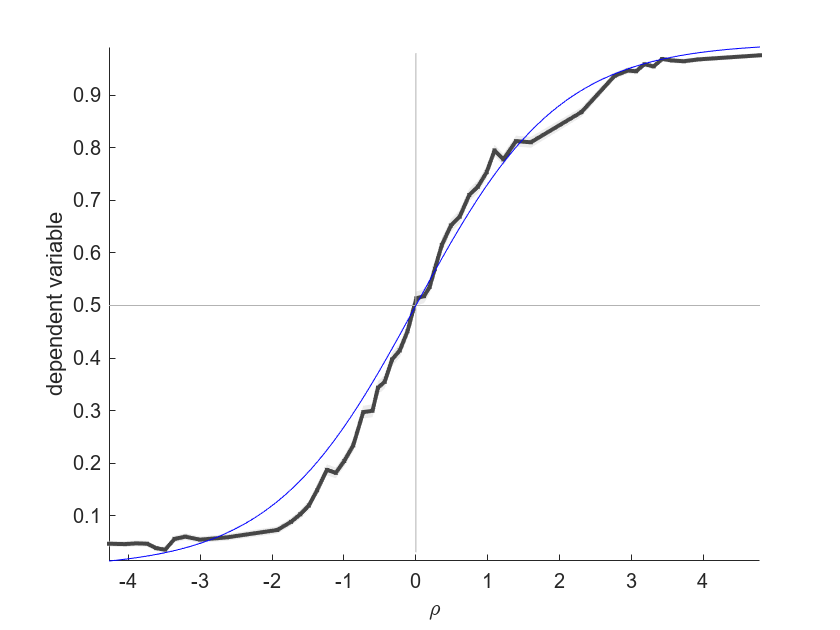

figure;
M.plot_data_vs_predictor(50);

Note: the number of bins (or quantiles) can be passed as extra option to` plot_data_vs_predictor.`

### Model metrics and diagnostics

There's a whole variety of metrics and diagnostics tool for your model. 

#### Variance Inflation Factor

The first diagnostics that is usually run *prior* to estimating weights is the Variance Inflation Factor. This tells you for each regressor how much the estimation of its corresponding weights will be affected by correlation with other regressors. A general rule of thumb is that values over VIF over 10 indicate serious issues with weight estimation and that you may have to remove this regressor for your model (although it also depends on factors such as sample size). In `gum `this is computed using `M.plot_vif().`

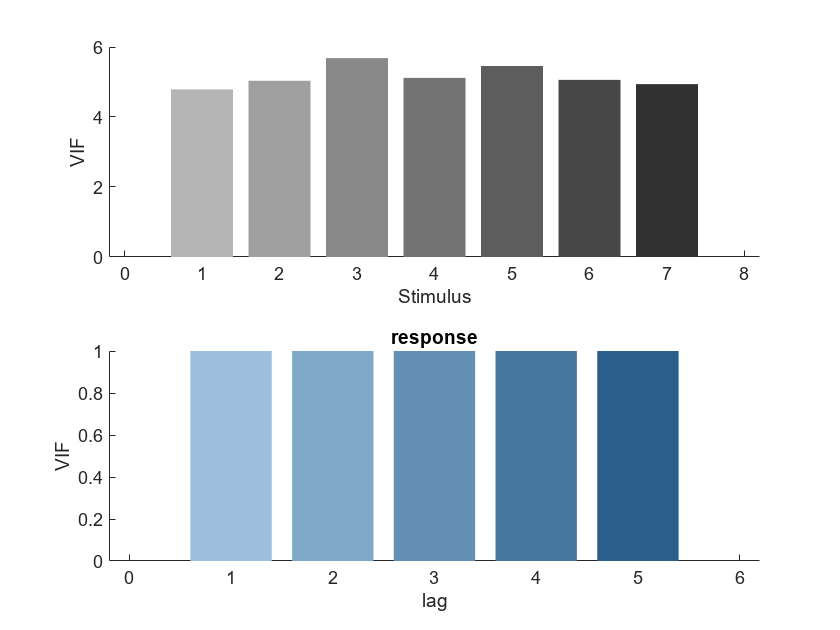

M = gum(T, 'resp ~ Stimulus + lag(response; Lags=1:5)');
figure;
M.plot_vif;

Here the values for the stimulus regressors are quite high (because they are highly correlated) but this is not an issue because we have many trials (but this means that single session estimates of stimulus weights are unreliable).

#### **Posterior covariance**

The VIF is an *a priori *measure of much regressor correlation can affect weight estimation. You can also analyze the model *a posteriori*, that is after estimating the weights. If the error bars for some weights are large, indicating unreliable estimation, look at the covariance matrix of the posterior over weights. This can help identify pairs of regressors with high (positive or negative) covariance, indicating that the model can train one for the other (see Wilson & Collins, eLife, Rule #XX):

M = gum(T, 'resp ~ Stimulus + lag(response|accuracy; Lags=1:10) + cat(session)','label','full');
M = M.fit();

Initial weight inference (1 starting points):*
HP fitting: iter 1, log evidence -28480.518843
HP fitting: iter 2, log evidence -28403.909284
HP fitting: iter 3, log evidence -28403.412561
HP fitting: iter 4, log evidence -28403.405605
HP fitting: iter 5, log evidence -28403.406074


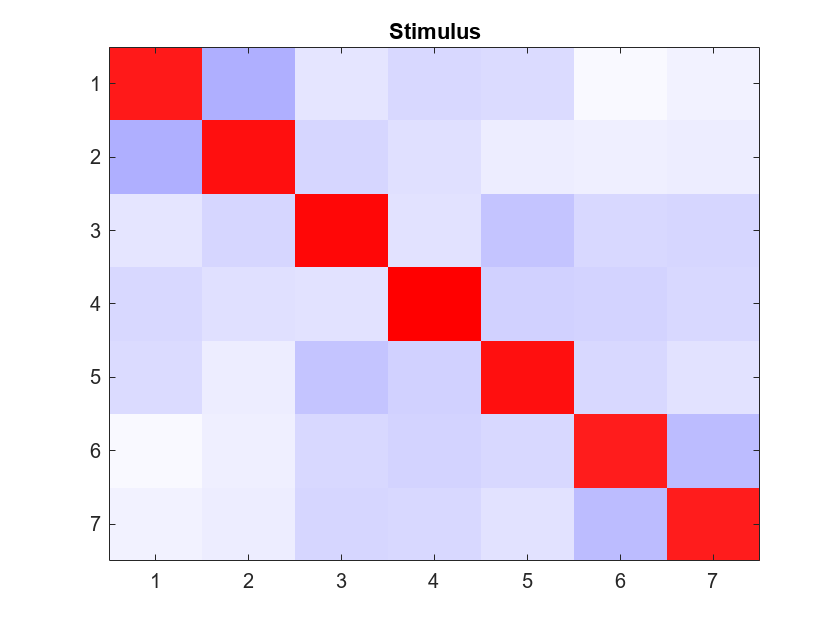

figure;
M.plot_posterior_covariance("Stimulus");

Here we see that the each of the stimulus weights is weakly correlated to the other weights in the posteriori, indicating good estimation.

#### **Model metrics**

Model metrics are printed in the model summary and are accessible in the `score` properties (e.g. `M.score`). Here are the most relevant ones :

- `LogLikelihood`, LogPrior` and `LogJoint refers to the log-likelihood of the weights `(`$\log p(y|\hat w)$), their log prior ($\log p(\hat w)$) and their log-joint ($\log p(y,\hat w)$), evaluated at the posterior mean weights $\hat w$.

- `accuracy` is the proportion of correctly predicted response (for binary or count data), according to the posterior mean weights $\hat w$. A correct prediction for binary data means $p(y=1)<0.5$ if $y=1$ and $p(y=1)>0.5$ if $y=0$.

- `AIC_infer`, `AICc_infer and BIC_infer` are the Akaike Information Criterion, corrected Akaike Information Criterion and Bayesian Information Criterion in the frequentist setting, i.e. the likelihood of the maximum likelihood weights $\hat w$ penalized by the number of weights. **Warning:** these metrics are only valid when no prior over weights is defined, i.e. when creating the model using `gum(T,fmla, 'prior','none')`.

- `LogEvidence` is the approximation to log of model evidence, i.e. the joint evidence marginalized over weights$\log p(y|\gamma)=\log \int_w p(y|w,\gamma)p(w|\gamma) dw$, which is a function of hyperparameters $\gamma$. This is the quantity that is maximized during `fit()`. 

- `AIC`, `AICc and BIC` are the Akaike Information Criterion, corrected Akaike Information Criterion and Bayesian Information Criterion in the bayesian setting, i.e. the log likelihood of the fitted hyperparameters $\gamma$ penalized by the number of fitted hyperparameters.

M = gum(T, 'resp ~ Stimulus + lag(response|accuracy; Lags=1:10) + cat(session)','label','full');
M = M.fit();

Initial weight inference (1 starting points):*
HP fitting: iter 1, log evidence -28480.518843
HP fitting: iter 2, log evidence -28403.909284
HP fitting: iter 3, log evidence -28403.412561
HP fitting: iter 4, log evidence -28403.405605
HP fitting: iter 5, log evidence -28403.406074


disp(M);

Generalized Unrestricted Model (GUM) object:  full ()
resp ~ Stimulus + lag(response|accuracy; Lags=1:10) + cat(session)
--------------------------------------------------------------------------------
            Type: GLM (   L2 prior)       Observations:       binomial
   nRegressorSet:          72137     ObservationBlock:              4
   nObservations:          72137          isEstimated:            yes
        isFitted:            yes              Dataset:               
     nParameters:            140      nFreeParameters:            139
              df:          71998     nFreeHyperparameters:              4
         scaling:              1        LogLikelihood:  -28101.529340
        LogPrior:     -66.138607             LogJoint:  -28167.667946
        accuracy:       0.824404             exitflag:            yes
     LogEvidence:  -28403.406074            BIC_infer:   57757.957488
       AIC_i

#### **Explained variance and predictor explained variance**

`The methods predictor_explained_variance`()` and plot_predictor_explained_variance() `indicates how much each set of regressors contributes to the explained variance. This is computed by looking at the variance explained by each set of regressors alone (with the same weight as in the full model, so in some cases the predictor explained variance can be negative).

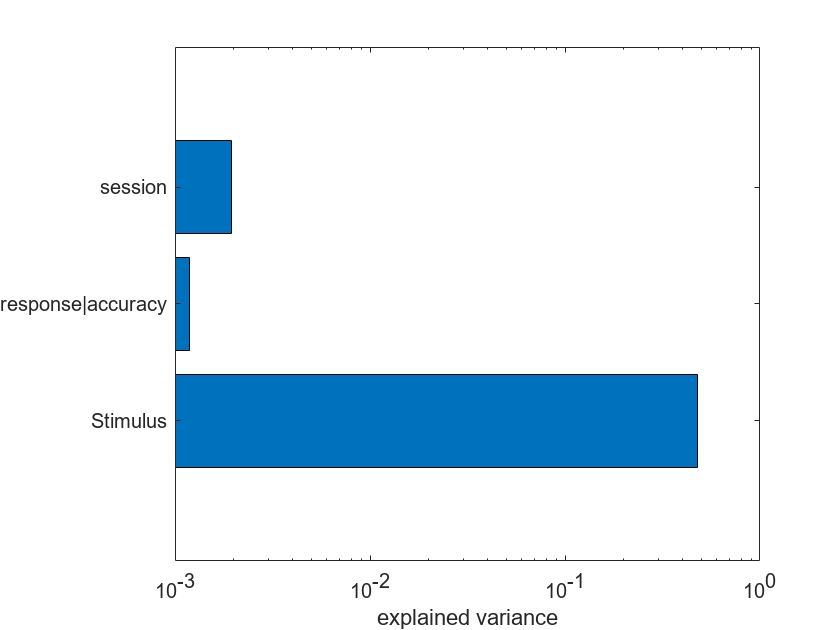

figure;
M.plot_predictor_explained_variance();
set(gca, 'xscale','log');

construct PREDICTOR?

### Model comparison

The metrics we described above form the basis of model comparison, i.e. assessing which model is better supported by the experimental data. Model comparison is performed using `plot_score()`, which takes as input any of the fields in `M.score` (or a combination of them). Here we plot the corrected AIC and BIC for three alternative models.

% defining two alternative models: in M2 the choice depends on previous
% response irrespective of their outcome; in M3 the choice does not depend
% on previous responses
M2 = gum(T, 'resp ~ Stimulus + lag(response; Lags=1:10) + cat(session)',...
    'label','simple history');
M3 = gum(T, 'resp ~ Stimulus + cat(session)',...
    'label','no history');

% fit these two other models
M2 = M2.fit();

Initial weight inference (1 starting points):*
HP fitting: iter 1, log evidence -28668.376752
HP fitting: iter 2, log evidence -28611.686852
HP fitting: iter 3, log evidence -28611.263910
HP fitting: iter 4, log evidence -28611.258418
HP fitting: iter 5, log evidence -28611.258843


M3 = M3.fit();

Initial weight inference (1 starting points):*
HP fitting: iter 1, log evidence -28805.467706
HP fitting: iter 2, log evidence -28764.373347
HP fitting: iter 3, log evidence -28763.864783
HP fitting: iter 4, log evidence -28763.857685
HP fitting: iter 5, log evidence -28763.858044


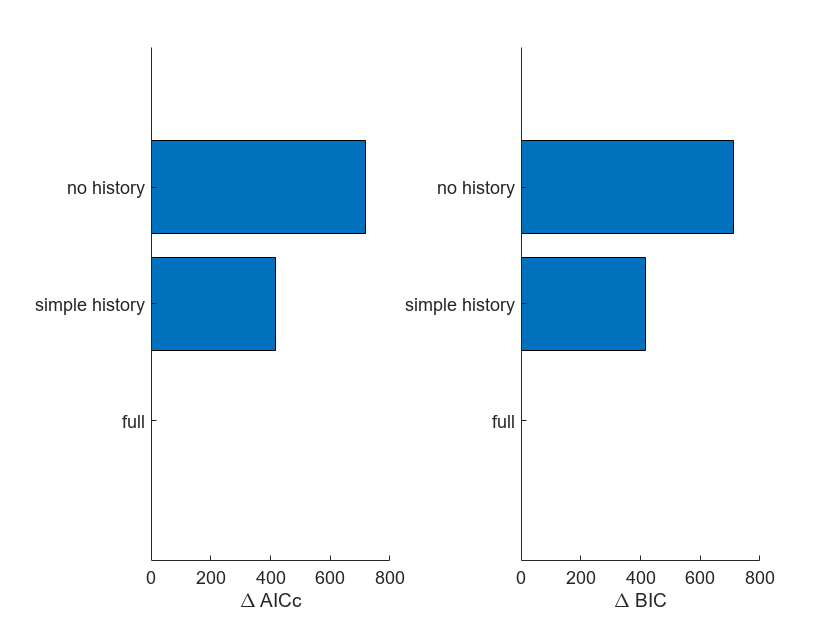

Mall = [M M2 M3];

% plot corrected AIC and BIC for the three models
% with the full model as reference (i.e. we plot the difference between a
% given model and the full model)
figure;
Mall.plot_score({'AICc','BIC'},'bar','full');

The penalized model evidence are larger than the two alternative models than for the original model, indicating that the original model better captures the animal choices.

See also methods `concatenate_score,` `export_scores_to_table `and `export_scores_to_csv.`

#### Model knock-outs

Oftentimes we want to compare a full model to variants where one or more sets of regressors haven been removed (or *knocked out*). You can remove sets of regressors from a model by using `M.knockout(lbl)` where `lbl `is the label of the set of regressors to be removed. If `lbl` is set to `"all"`, then an array of models is created, with each model being knocked-out a specific set of regressors. 

Here we apply this to compare the accuracy of a model that takes into account stimulus evidence, history effects and session-wise biases to models where one of these three components is missing. This gives an indication of how much each of these components contribute to explaining behavior.

% creating a model with all three components and estimating weights
M = gum(T, 'resp ~ Stimulus + lag(response; Lags=1:5) + cat(session)','label','full');
M = M.infer();

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-28346.691787
Computing posterior covariance...done



% creating three knock-out models and estimating weights for each of them
Mko = M.knockout('all');
Mko = Mko.infer();

Inferring weights for model 1/3:  Stimulus knock-out ()
Evaluating prior covariance matrix...done
****x
converged after 5 iterations, log-joint:-49230.241160
Computing posterior covariance...done

Inferring weights for model 2/3:  lag(response) knock-out ()
Evaluating prior covariance matrix...done
****
converged after 4 iterations, log-joint:-28521.849169
Computing posterior covariance...done

Inferring weights for model 3/3:  cat(session) knock-out ()
Evaluating prior covariance matrix...done
****
converged after 4 iterations, log-joint:-29645.683040
Computing posterior covariance...done



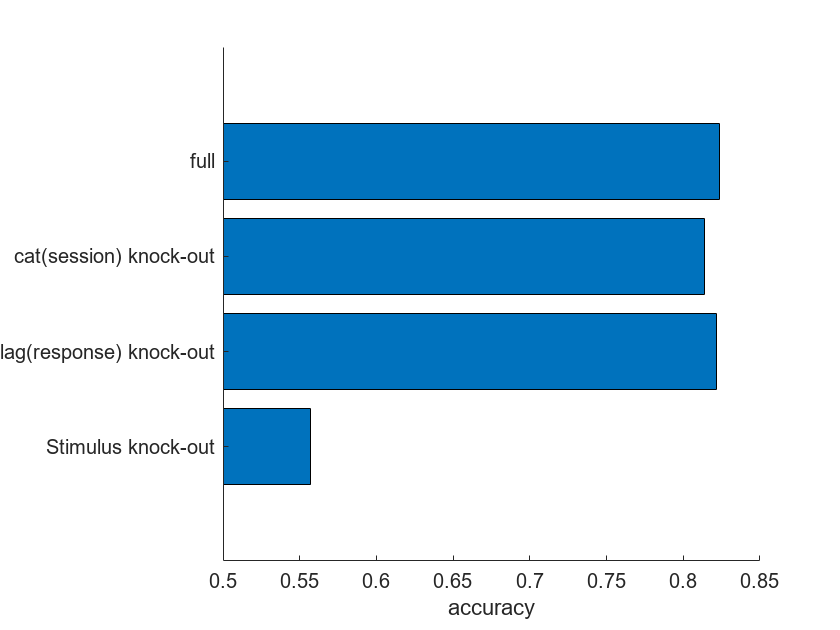


% concatenate full model with knockouts and plotting accuracy for each
figure;
Mall = [Mko M];
Mall.plot_score('accuracy');
xlim([.5 .85]);

### Model simulation

You can simulate the regression model using estimated weights with the `sample `method:

[M, smp] = M.Sample;
size(smp)

ans =        72137           1


If you would like to simulate the model for a different dataset than the one that was use to estimate the weights, follow the code below:

% fit a different model for each session
Mpop = gum(T, 'resp|session ~ Stimulus');

% estimate weights for session 1
Mpop(1) = Mpop(1).infer();

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-122.791693
Computing posterior covariance...done



% copy weights to model for session 2
Mpop(2) = Mpop(2).set_weights_from_model(Mpop(1));

% sample model with this set of weights
[Mpop(2), smp2] = Mpop(2).Sample;

The samples are stored in a vector in `M.Predictions.sample`. Samples are generated by using the mean of the posterior distribution on weights (i.e. the Maximum A Posteriori weights).  You can use `M.Sample_Observations_From_Posterior` to use a double sampling strategy, where a set of weights is first samples from the posterior on weights, and then observations are sampled based on this set of weights.